clear

syms f(x)
% f(x) = x^2;
f(x) = (erf((x-1/2)*4)-0.9);
% f(x) = -sin(x*2*pi)-cos(x*pi);
g = sym(2);
h = sym(0);
m = sym(-2);
q = sym(-4);
E = sym(1);
I = sym(1);

EX = computeExactSolution(E,I,f,g,h,m,q);

nELEM = 2;
eDegree = 3;
continuity = eDegree-1;
contVector = [-1 continuity*ones(1,nELEM-1) -1];
FE = main(nELEM, eDegree, contVector, f, g, h, m, q, E*I);

K = FE.LinearSystem.K

$$K = \left[\begin{array}{ccc} 48 & -48 & 24\\ -48 & 192 & -132\\ 24 & -132 & 96 \end{array}\right]$$

F = FE.LinearSystem.F

d = FE.LinearSystem.d

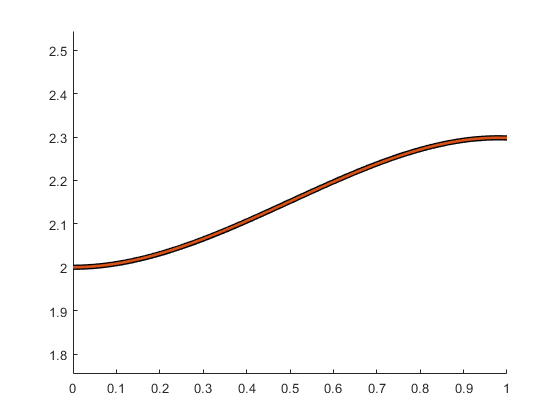


figure
hold on
fplot(EX.U,EX.domain,'k','LineWidth',4)
fplot(FE.U,EX.domain,"LineWidth",2)
xlim([EX.domain])
axis equal

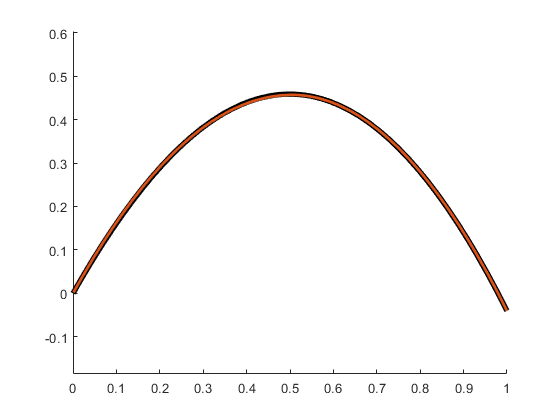



figure
hold on
fplot(diff(EX.U),EX.domain,'k','LineWidth',4)
fplot(diff(FE.U),EX.domain,"LineWidth",2)
xlim([EX.domain])
axis equal

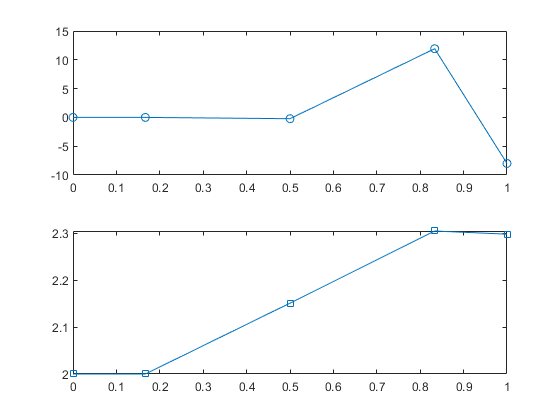


figure 
subplot(2,1,1)
plot(FE.Spline.nodes,[0; 0; FE.LinearSystem.F],'-o')
subplot(2,1,2)
plot(FE.Spline.nodes, FE.LinearSystem.d,'-s')

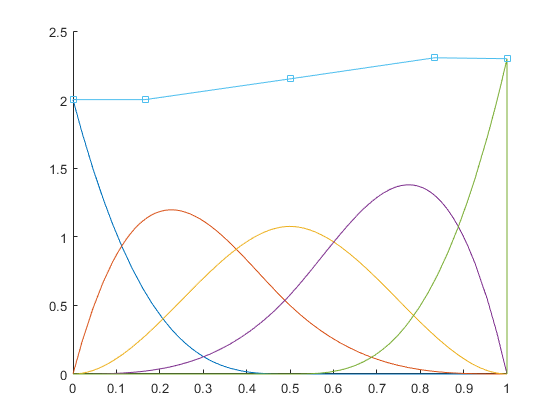


figure
hold on
fplot(FE.Spline.basis.functions .* d ,EX.domain)
plot(FE.Spline.nodes, FE.LinearSystem.d,'-s')